**Gaurang Ruparelia BMFLC**

Part 1: Create signal

t = 0:0.001:120;    % time vector
N = length(t);      % signal length
nu = 0.0001;         % adaptive gain

% Mp voluntary (high frequency) row vector
Mpv = sin(t) + 2*sin(2*t) + 3*sin(3*t) + cos(t) + 2*cos(2*t) + 3*cos(3*t);
% Mp involuntary (low frequency) row vector
Mpi = 0.1*sin(30*t) + 0.1*sin(35*t) + 0.1*cos(30*t) + 0.1*cos(35*t);
% combine the voluntary frequencies and involuntary frequencies row vector
Mp = Mpi + Mpv

Mp =     6.2000    6.2204    6.2405    6.2604    6.2799    6.2993    6.3183    6.3370    6.3555    6.3736    6.3915    6.4090    6.4263    6.4432    6.4598    6.4761    6.4920    6.5077    6.5230    6.5379    6.5526    6.5669    6.5808    6.5945    6.6077    6.6207    6.6333    6.6456    6.6575    6.6691    6.6804    6.6913    6.7019    6.7122    6.7221    6.7317    6.7410    6.7500    6.7587    6.7671    6.7752    6.7829    6.7904    6.7976    6.8045    6.8112    6.8175    6.8236    6.8295    6.8351


Part 2: Create frequency range

w_a = 1;    % minimum freq
w_b = 35;    % maximum freq
beta = 2000;   % # freq between w_a and w_b (try different values)
freq_vec = linspace(w_a,w_b,beta);

Part 3: Create placeholder vectors

Mp_hat = zeros(1,N);
theta = zeros(1,2*beta); % [1, beta] is for "a" and [beta+1, beta+beta] is for "b"
phi = zeros(1,2*beta);

Part 4: Estimate Mp_hat

for i = 1:N
    for j = 1:beta
        phi(j) = sin((w_a+freq_vec(j))*t(i));         % sine component
        phi(j+beta) = cos((w_a+freq_vec(j))*t(i));    % cosine component
    end
    Mp_hat(i) = phi*theta';
    Err = Mp(i) - Mp_hat(i);
    theta = theta + 2*nu*phi*Err;              % update theta using error
end


Part 5: Plot Mp_hat and Mp on the same figure

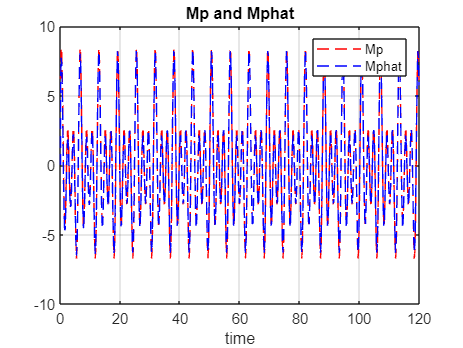


plot(t, Mp,"r--", t, Mp_hat,'b--')
title("Mp and Mphat")
axis([0 120 -10 10]) % set time on x-axis betweeen 0 to 120 and y-axis between 10 and -10
xlabel("time")
legend('Mp', "Mphat")
grid on

Part 6: Extract the voluntary and involuntary component

*Hint: the final theta contains the weights for the fourier series. The first half contains the weights ('*$\lambda$*') for the sine components, and the second half contains the weight for the cosing components ('*$\vartheta$*'). These are ordered from lowest frequency to the highest frequency.*


Mp_v_hat = zeros(1,N);
w_cutoff = 2*6.8; % 2 Hz in rad/sec
idx = length(find(freq_vec <= w_cutoff));
lambda = theta(1:idx);
vartheta = theta(beta+1:beta+idx);
theta_v = [lambda vartheta];
phi=zeros(1,2*idx);
for i = 1:N
    for j = 1:idx
        phi(j) = sin(freq_vec(j)*t(i));         % sine component
        phi(j+idx) = cos(freq_vec(j)*t(i));    % cosine component
    end
    Mp_v_hat(i) = phi*theta_v';
end

Part 7: Plot the estimated voluntary Mp_v_hat with the actual Mp_v

% To Do:
Mp_v_hat

Mp_v_hat =    -4.9247   -4.8747   -4.8246   -4.7745   -4.7243   -4.6741   -4.6238   -4.5734   -4.5230   -4.4725   -4.4220   -4.3715   -4.3209   -4.2703   -4.2197   -4.1690   -4.1183   -4.0676   -4.0168   -3.9661   -3.9153   -3.8645   -3.8137   -3.7629   -3.7121   -3.6613   -3.6105   -3.5597   -3.5089   -3.4582   -3.4074   -3.3567   -3.3059   -3.2552   -3.2046   -3.1539   -3.1033   -3.0528   -3.0022   -2.9517   -2.9013   -2.8509   -2.8005   -2.7502   -2.7000   -2.6498   -2.5997   -2.5496   -2.4996   -2.4497


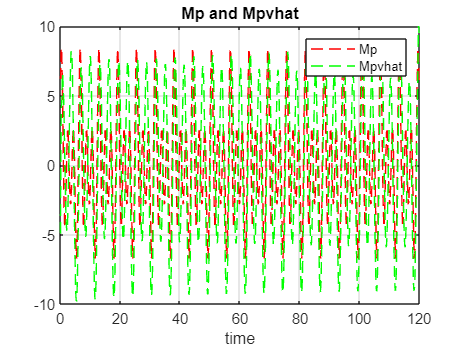

plot(t, Mp,"r--", t, Mp_v_hat,'g--')
title("Mp and Mpvhat")
axis([0 120 -10 10]) % set time on x-axis betweeen 0 to 120 and y-axis between 10 and -10
xlabel("time")
legend('Mp', "Mpvhat")
grid on